# **Design Summary**

## **Wireless Communications: Performance Analysis Verification via Monte Carlo Simulations**

Author: Albedo (Zheyu Wang)

Created Date: 03.06.2025

Last Modified: 10.06.2025

Clarification: *'Albedo' is an informal English name adopted by the author due to the phonetic difficulty of the given name 'Zheyu'.*

### **Read Me**

It should be noted that the subsequent plots are generated using `plot` rather than `semilogy` without overlaying theoretical performance curves; therefore, the results presented in this version **should be considered for illustrative purposes only**.

#### 1 Channel Models

Task: Generate the following six simulation environments

- Laplacian Noise channels

- AWGN channels

- Rayleigh fading and AWGN channels

- Rician fading and AWGN channels

- Randomly deployed users over Rayleigh fading and AWGN channels

- Rician deployed users over Rayleigh fading and AWGN channels

Note: In the simulation process, the transmit power should be adjusted according to the required SNR. However, since I am only conducting a qualitative study of the implementation of the six models, the SNR is fixed at $\gamma_b = 0 \text{ dB}$ , and thus the transmit power $E_b$ is set to a constant value of 1 because the Noise Power is $N_0 = 1$.

% Parameters
N = 1e6;                                % Number of Monte Carlo samples
N0 = 1;                                 % Noise power
gamma_b_dB = 0:1:15;                    % SNR in dB
gamma_b = 10.^(gamma_b_dB / 10);        % Linear SNR
alpha = 2.2;                            % Path loss exponent
R = 3;                                  % Deployment radius
K = 5;                                  % Rician K-factor
h_d = 1;                                % LoS component
d = 1;                                  % Fixed User Distance
h_l = d ^ (-alpha);                     % Path loss

% Generate bits and BPSK symbols
x = randi([0 1], 1, N);
s = 2 * x - 1;                          % BPSK mapping
Eb = gamma_b .* N0;                     % Required signal energy per bit

% NOTE: 
%   I only perform a qualitative analysis without using a loop, 
%   so I calculate the case with an SNR of 0 only.
s_scaled = sqrt(Eb(1)) * s;             % Scale BPSK symbols to adjust signal energy

% 1. Generate Laplacian Impulsive Noise Samples
sparsity_ratio = 0.5;                   
mask = rand(1, N) < sparsity_ratio;   
b = sqrt(1/2);                         
% Method 1 Using MATLAB Build-in Function
% amplitudes = laprnd(N,1,0,b); 
% Method 2 Generate Laplacian Destribution Using 
U = rand(1, N) - 0.5; 
amplitudes = -b * sign(U) .* log(1 - 2 * abs(U));
Noise_La = mask .* amplitudes;

% 2. Generate AWGN Samples
Noise_AWGN = N0 * randn(1, N);

% 3. Rayleigh Fading + AWGN
sigma = 1/sqrt(2);
rayleigh_gain = raylrnd(sigma, 1, N);
% h_complex = (randn(N,1) + 1i * randn(N,1)) * sigma;
% rayleigh_gain = abs(h_complex);
r_rayleigh = abs(rayleigh_gain) .* s_scaled + Noise_AWGN;
% Rayleigh Fading with Path Loss
r_ray = h_l * abs(rayleigh_gain) .* s_scaled + Noise_AWGN;

% 4. Rician Fading + AWGN
% chan = comm.RicianChannel(tx, fd, K);
% h = filter(chan, tx);
s = sqrt(K / (K + 1));
sigma2 = sqrt(1 / (2*(K + 1)));
rician_gain = s + sigma2 * (randn(1, N) + 1i*randn(1, N));
r_rician = abs(rician_gain) .* s_scaled + Noise_AWGN;
% Rician Fading with Path Loss
r_ri = h_l * abs(rician_gain) .* s_scaled + Noise_AWGN;

% 5. Random User Deployment
U_d = rand(1, N);
d_random = R .* sqrt(U_d);
h_l_random = d_random .^ (-alpha); 

% Rayleigh + AWGN
r_ray_random = h_l_random .* abs(rayleigh_gain) .* s_scaled + Noise_AWGN;
% Rician + AWGN
r_ri_random = h_l_random .* abs(rician_gain) .* s_scaled + Noise_AWGN;



#### 2 Noise Modek Visualization

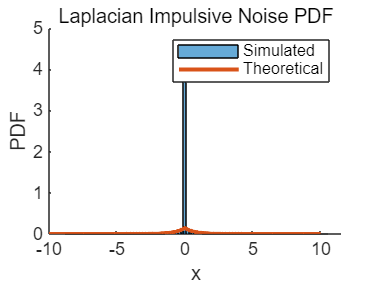

% Parameters
N = 1e6;
N0 = 1;                             % Noise power
x = linspace(-10, 10, 1000);        % Value range for plotting

% Simulated Laplacian Noise Samples
sparsity_ratio = 0.2;
mask = rand(1, N) < sparsity_ratio;
b = sqrt(1/2); 
U = rand(1, N) - 0.5;
Noise_La_0 = -b * sign(U) .* log(1 - 2 * abs(U));
Noise_La = mask .* Noise_La_0;

% Analytical PDF of Laplace noise
pdf = (1 / sqrt(2 * N0)) * exp(-sqrt(2 / N0) * abs(x));
% Analytical CDF of Laplace noise
cdf = zeros(size(x));
cdf(x <= 0) = 0.5 * exp(sqrt(2 / N0) * x(x <= 0));
cdf(x > 0) = 1 - 0.5 * exp(-sqrt(2 / N0) * x(x > 0));
% Analytical PDF of Laplace Impulsive noise
pdf_mixed = sparsity_ratio * pdf;

% PDF
figure; hold on;
histogram(Noise_La, 100, 'Normalization','pdf');
plot(x, pdf_mixed, 'LineWidth', 2);
title('Laplacian Impulsive Noise PDF');
xlabel('x'); ylabel('PDF');
legend("Simulated","Theoretical");

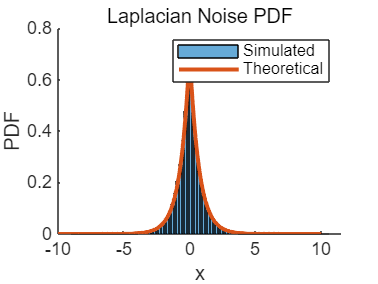

figure; hold on;
histogram(Noise_La_0, 100, 'Normalization','pdf');
plot(x, pdf, 'LineWidth', 2);
title('Laplacian Noise PDF');
xlabel('x'); ylabel('PDF');
legend("Simulated","Theoretical");

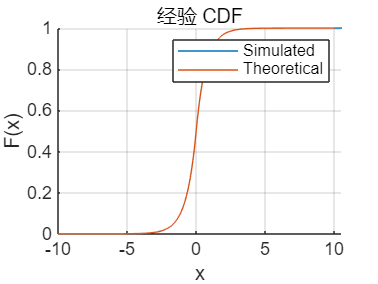


% CDF
figure; hold on;
% cdfplot(Noise_La);
cdfplot(Noise_La_0);
plot(x, cdf);
legend("Simulated","Theoretical");

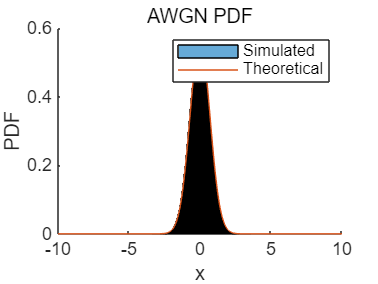



% Simulated AWGN Samples
Noise_AWGN = sqrt(N0/2) * randn(1, N);
% Analytical PDF & CDF
pdf_awgn = normpdf(x, 0, sqrt(N0/2));    
cdf_awgn = normcdf(x, 0, sqrt(N0/2));    % MATLAB built-in for Gaussian CDF

% AWGN Noise
% PDF
figure; hold on;
histogram(Noise_AWGN, 100, 'Normalization','pdf');
plot(x, pdf_awgn);
legend("Simulated","Theoretical");
title('AWGN PDF');
xlabel('x'); ylabel('PDF');

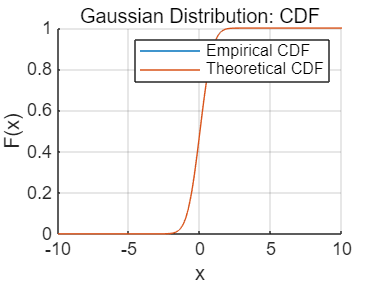

% CDF
figure; hold on; 
cdfplot(Noise_AWGN); 
plot(x, cdf_awgn);
legend("Simulated","Theoretical");
title('Gaussian Distribution: CDF');
legend('Empirical CDF', 'Theoretical CDF');

Some **Statistics** to verify the variables.

% Mean
mean_gaussian = mean(Noise_AWGN)

mean_gaussian = -0.0011

mean_laplace = mean(Noise_La)

mean_laplace = -5.0588e-04

mean_la_0 = mean(Noise_La_0)

mean_la_0 = -5.7939e-04

% Variance
var_gaussian = var(Noise_AWGN)

var_gaussian = 0.4997

var_laplace = var(Noise_La)

var_laplace = 0.1988

var_la_0 = var(Noise_La_0)

var_la_0 = 0.9958

% % Skewness 偏度
% skew_gaussian = skewness(Noise_AWGN)
% skew_laplace = skewness(Noise_La)
% % Kurtosis 峰度
% kurt_gaussian = kurtosis(Noise_AWGN)
% kurt_laplace = kurtosis(Noise_La)

% Display Table
NoiseType = {'AWGN'; 'Laplacian'; 'Laplacian & Impulsive'};
MeanValue = [mean_gaussian; mean_la_0; mean_laplace];
Variance = [var_gaussian; var_la_0; var_laplace];
T = table(NoiseType, MeanValue, Variance, ...
    'VariableNames', {'NoiseType', 'Mean', 'Variance'})

T = 3×3 table
            NoiseType               Mean        Variance
    _________________________    ___________    ________

    {'AWGN'                 }     -0.0011276    0.49967 
    {'Laplacian'            }    -0.00057939    0.99581 
    {'Laplacian & Impulsive'}    -0.00050588    0.19878 


The following program is used to plot the **Time Series of the Noise**

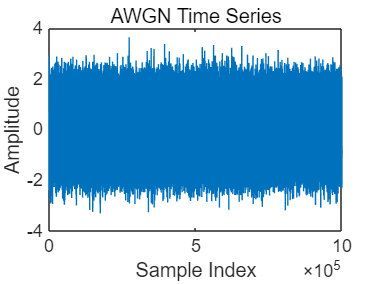

% AWGN
figure;
plot(Noise_AWGN);
title('AWGN Time Series');
xlabel('Sample Index'); ylabel('Amplitude');

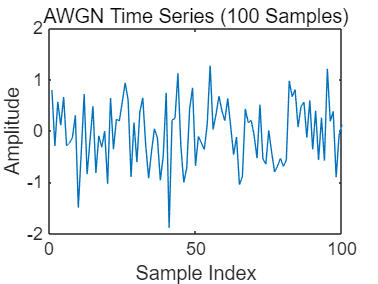

% Randomly select 100 samples of AWGN
figure;
k = 567;
plot(Noise_AWGN(k:k + 100));
title('AWGN Time Series (100 Samples)');
xlabel('Sample Index'); ylabel('Amplitude');
xlim([0 100]);

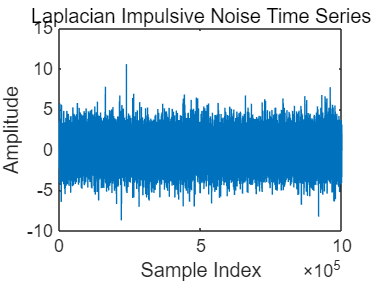


% Laplacian Impulsive Noise
figure;
plot(Noise_La);
title('Laplacian Impulsive Noise Time Series');
xlabel('Sample Index'); ylabel('Amplitude');

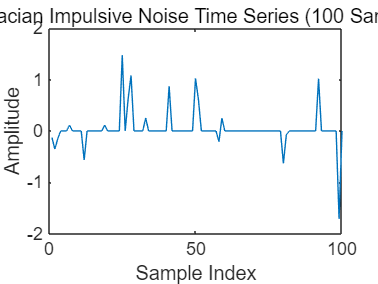

% Randomly select 100 samples of Laplacian Impulsive noise
figure;
k = 567;
plot(Noise_La(k:k + 100));
title('Laplacian Impulsive Noise Time Series (100 Samples)');
xlabel('Sample Index'); ylabel('Amplitude');
xlim([0 100]);

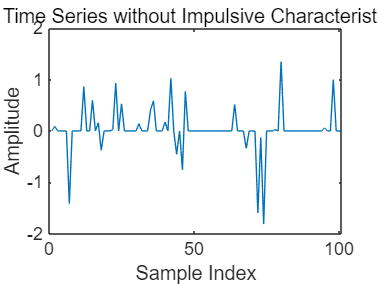

% Randomly select 100 samples of Laplacian noise without impulsive characteristics
figure;
k = 900;
plot(Noise_La(k:k + 100));
title('Laplacian Noise Time Series without Impulsive Characteristics (100 Samples)');
xlabel('Sample Index'); ylabel('Amplitude');

#### 3 Simulation

Part 1 (Channel Models) qualitatively discussed how to generate additive noise, multiplicative fading, and static or dynamic path loss caused by user location. In this part, the impact of different signal-to-noise ratio (SNR) conditions on BER and connection outage probability will be considered.


$$\text{BER} = \frac{\text{Number of errors}}{\text{Total number of bits}}$$



$$\text{Effective Gain}= \text{Passing Loss} \cdot \text{Fading Gain} < \text{threshold}$$


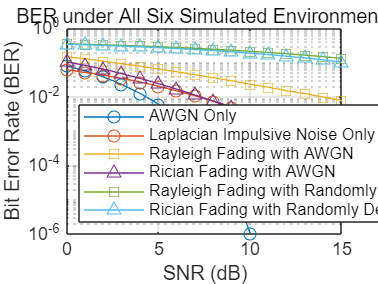

% Parameters 
N = 1e6;                                % Number of Monte Carlo samples
N0 = 1;                                 % Noise power
gamma_b_dB = 0:1:15;                    % SNR in dB
gamma_b = 10.^(gamma_b_dB / 10);        % Linear SNR
alpha = 2.2;                            % Path loss exponent
R = 3;                                  % Deployment radius
K = 5;                                  % Rician K-factor
d_fixed = 1;                            % Fixed user distance
C = 1.2;                                % Target Rate
threshold = 2 ^ C- 1;                   % Outage threshold

% Initialization of result arrays
ber_awgn = zeros(size(gamma_b));
ber_rayleigh = zeros(size(gamma_b));
ber_rician = zeros(size(gamma_b));
outage_rayleigh = zeros(size(gamma_b));
outage_rician = zeros(size(gamma_b));

for i = 1:length(gamma_b)
    % Generate random bits and BPSK symbols
    x = randi([0 1], 1, N);
    s = 2 * x - 1;

    % Compute Eb and scale BPSK symbols
    Eb = gamma_b(i) * N0;
    s_scaled = sqrt(Eb) * s;

    % AWGN Noise samples
    Noise_AWGN = sqrt(N0/2) * randn(1, N);
    % Laplacian Impulsive Noise
    sparsity_ratio = 0.5;
    mask = rand(1, N) < sparsity_ratio;
    b = sqrt(1/2); 
    U = rand(1, N) - 0.5; 
    amplitudes = -b * sign(U) .* log(1 - 2 * abs(U));
    Noise_La = mask .* amplitudes;
    % Rayleigh Fading Gain
    rayleigh_gain = raylrnd(1/sqrt(2), 1, N);
    % Rician Fading Gain 
    s_r = sqrt(K / (K + 1));
    sigma_r = sqrt(1 / (2 * (K + 1)));
    rician_gain = abs(s_r + sigma_r * (randn(1, N) + 1i * randn(1, N)));
    % Pass Loss Gain
    h_l = d_fixed^(-alpha);             % Fixed path loss
    U_d = rand(1, N);
    d_random = R .* sqrt(U_d);
    h_l_random = d_random .^ (-alpha);  % Random path loss


    % ### 1 ### AWGN Only channel
    r_awgn = s_scaled + Noise_AWGN;
    % BER
    x_hat_awgn = r_awgn > 0;
    ber_awgn(i) = sum(x_hat_awgn ~= x) / N;

    % ### 2 ### Laplacian Impulsive Noise Only
    r_la = s_scaled + Noise_La;
    % BER
    x_hat_la = r_la > 0;
    ber_la(i) = sum(x_hat_la ~= x) / N;

    % ### 3 ### Rayleigh fading Only
    r_ray = rayleigh_gain .* s_scaled;
    % BER
    x_hat_ray = r_ray > 0;
    ber_ray(i) = sum(x_hat_ray ~= x) / N;

    % ### 4 ### Rician fading Only
    r_ri = rician_gain .* s_scaled;
    % BER
    x_hat_ri = r_ri > 0;
    ber_ri(i) = sum(x_hat_ri ~= x) / N;


    % ### 5 ### Rayleigh fading + AWGN
    r_rayleigh = rayleigh_gain .* s_scaled + Noise_AWGN;
    x_hat_rayleigh = r_rayleigh > 0;
    ber_rayleigh(i) = sum(x_hat_rayleigh ~= x) / N;
    outage_rayleigh(i) = sum((rayleigh_gain) .^2 <= threshold/gamma_b(i)) / N;
    
    % ### 6 ### Rician fading  + AWGN
    % BER
    r_rician = rician_gain .* s_scaled + Noise_AWGN;
    x_hat_rician = r_rician > 0;
    ber_rician(i) = sum(x_hat_rician ~= x) / N;
    % Outage Probablity
    outage_rician(i) = sum((rician_gain) .^2 <= threshold/gamma_b(i)) / N;

    % ### 7 ### Rayleigh fading + AWGN + Randomly deployed users
    r_rayleigh = h_l_random .* rayleigh_gain .* s_scaled + Noise_AWGN;
    x_hat = r_rayleigh > 0;
    ber_rayleigh_random(i) = sum(x_hat ~= x) / N;
    outage_rayleigh_random(i) = sum((h_l_random .*rayleigh_gain) .^2 <= threshold/gamma_b(i)) / N;

    % ### 8 ### Rician fading + AWGN + Randomly deployed users
    % BER
    r_rician = h_l_random .* rician_gain .* s_scaled + Noise_AWGN;
    x_hat = r_rician > 0;
    ber_rician_random(i) = sum(x_hat ~= x) / N;
    % Outage Probablity
    outage_rician_random(i) = sum((h_l_random .*rician_gain) .^2 <= threshold/gamma_b(i)) / N;
end

% Plot BER results
figure;
semilogy(gamma_b_dB, ber_awgn, '-o', 'DisplayName', 'AWGN Only'); hold on;
semilogy(gamma_b_dB, ber_la, '-o', 'DisplayName', 'Laplacian Impulsive Noise Only');
semilogy(gamma_b_dB, ber_rayleigh, '-s', 'DisplayName', 'Rayleigh Fading with AWGN');
semilogy(gamma_b_dB, ber_rician, '-^', 'DisplayName', 'Rician Fading with AWGN');
semilogy(gamma_b_dB, ber_rayleigh_random, '-s', 'DisplayName', 'Rayleigh Fading with Randomly Deployed Users');
semilogy(gamma_b_dB, ber_rician_random, '-^', 'DisplayName', 'Rician Fading with Randomly Deployed Users');
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER under All Six Simulated Environments');
legend('Location', 'southwest'); grid on;

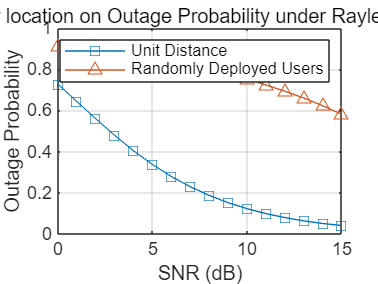


% Plot outage probability results
figure;
plot(gamma_b_dB, outage_rayleigh, '-s', 'DisplayName', 'Unit Distance'); hold on;
plot(gamma_b_dB, outage_rayleigh_random, '-^', 'DisplayName', 'Randomly Deployed Users');
xlabel('SNR (dB)');
ylabel('Outage Probability');
title('The impact of user location on Outage Probability under Rayleigh Fading Channels');
legend; grid on;

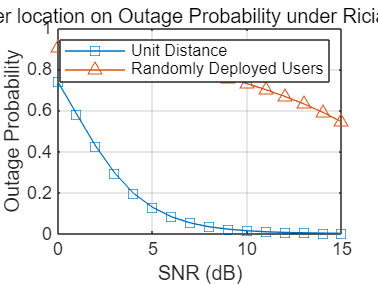


figure;
plot(gamma_b_dB, outage_rician, '-s', 'DisplayName', 'Unit Distance'); hold on;
plot(gamma_b_dB, outage_rician_random, '-^', 'DisplayName', 'Randomly Deployed Users');
xlabel('SNR (dB)');
ylabel('Outage Probability');
title('The impact of user location on Outage Probability under Rician Fading Channels');
legend; grid on;

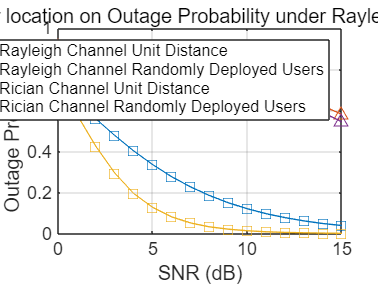


% In one Figure
figure;
plot(gamma_b_dB, outage_rayleigh, '-s', 'DisplayName', 'Rayleigh Channel Unit Distance'); hold on;
plot(gamma_b_dB, outage_rayleigh_random, '-^', 'DisplayName', 'Rayleigh Channel Randomly Deployed Users');
plot(gamma_b_dB, outage_rician, '-s', 'DisplayName', 'Rician Channel Unit Distance'); hold on;
plot(gamma_b_dB, outage_rician_random, '-^', 'DisplayName', 'Rician Channel Randomly Deployed Users');
xlabel('SNR (dB)');
ylabel('Outage Probability');
title('The impact of user location on Outage Probability under Rayleigh Fading Channels');
legend; grid on;